# Gruppe1 PBL - Main

Load the measured data into the workspace.

After this part any of the modules can be executed savely since it resets the input.

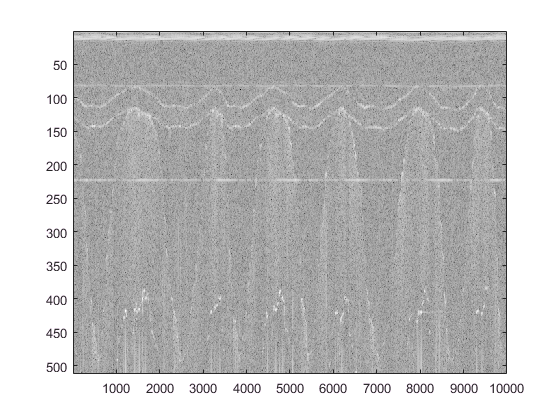

close all;
clear all;
% the filename is put into its own variable so we can display and save it in the submodules along with the parameters
% to remember "working configurations"
% filename = "09052017034909__ascan_3.bin";
filename = "09052017034420__ascan_2.bin";
filehandle = fopen(filename);
mscan = fread(filehandle,'float32');

bildhoehe = 512; % vorgegeben von Tutor

C = reshape(mscan,bildhoehe,[]);
clear mscan; % free up memory
% Scaling of values to [0,1] for compatibility with imshow / imagesc
C = C / max(C(:));

% Auswahl des anzuzeigenden Bereichs
C = C(:,1:10000);
original = C;

colormap gray;
imagesc(C);

Convert the MScan into BScans using one of our methods:

09052017034420__ascan_2.bin
    "calculating diff …"    "1"    "1626"    " and "    "2"    "3313"    ":"    "1687"

    "1626"    " is away far enough f…"    "3313"    " so we are adding it"

    "calculating diff …"    "2"    "3313"    " and "    "3"    "4618"    ":"    "1305"

    "3313"    " is away far enough f…"    "4618"    " so we are adding it"

    "calculating diff …"    "3"    "4618"    " and "    "4"    "6148"    ":"    "1530"

    "4618"    " is away far enough f…"    "6148"    " so we are adding it"

    "calculating diff …"    "4"    "6148"    " and "    "5"    "7637"    ":"    "1489"

    "6148"    " is away far enough f…"    "7637"    " so we are adding it"

    "calculating diff …"    "5"    "7637"    " and "    "6"    "9400"    ":"    "1763"

    "7637"    " is away far enough f…"    "9400"    " so we are adding it"



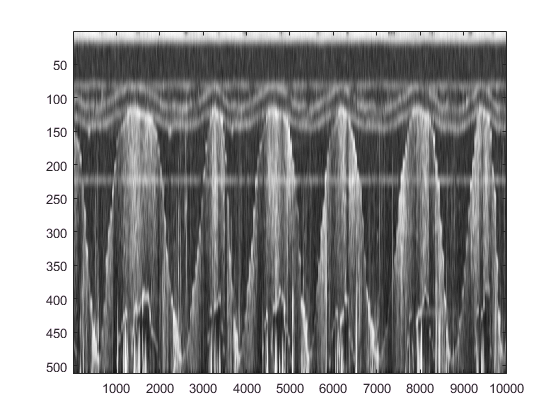

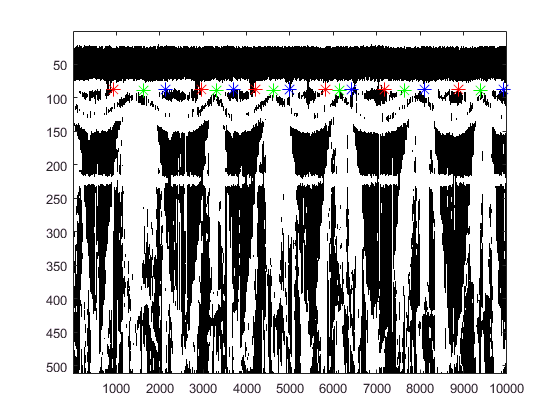

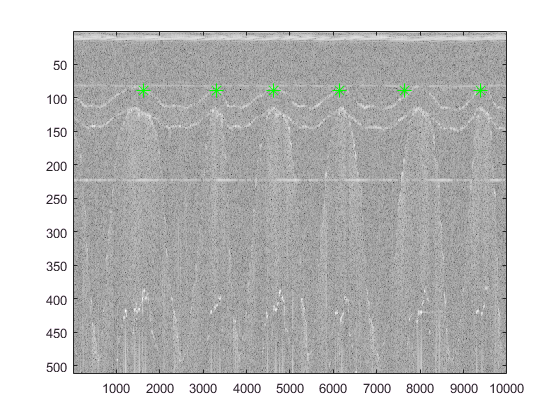

PBL_MScan2Bscan_Gapfinder();

% Alexandra's method
% Alex's method

Filter artefacts

25% erreicht
50% erreicht
75% erreicht
100% erreicht
100% erreicht


PBL_Filter_Artefacts();

Interpolation and coordinate transformation

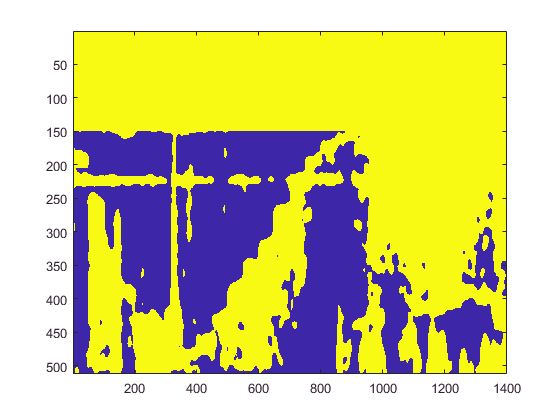

FinishedBScan = Artefact1(:,3500:4900); %todo, artefact 2 algo left out here
FinishedBScan(1:150,:) = 1;
figure; %attempt to correct the image display
imagesc(FinishedBScan);

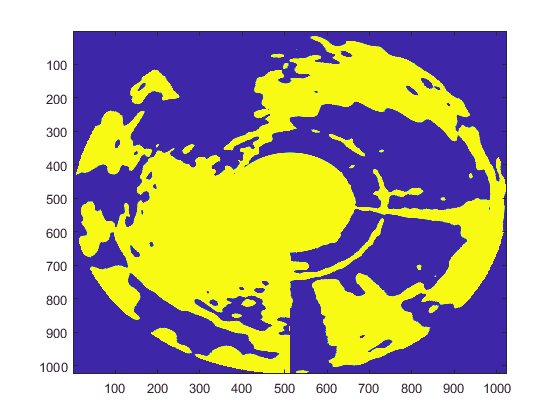

figure;
N = 512*2;
M = N;
imR = PolarToIm (FinishedBScan, 0, 1, M, N);
imagesc(imR);